data = double(table2array(readtable('/home/mist/Documents/projects/Brain/code/tempn1.csv')));

disp('loading WF PCA projections')

loading WF PCA projections



[dims, time] = size(data);


n=20;
l=n/2

l = 10

% transpose for Umap
% data = data./vecnorm(data,2,2);
data_r = data(1:l,1:1000);
data_small = data(1:l,1:2000);
    
norm(data(:,1))    

ans = 1.0000

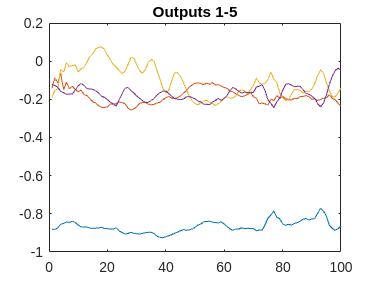


% %   We take a white noise sequence of 4000 points as (unmeasured) input e.
% %   The simulated output is stored in y. (chol(r) makes cov(e) = r).

%     N = 4000;
%     e = randn(N,l)*chol(r);
%     x0 = [10;-10];
%     y = dlsim(a,k,c,eye(l),e,x0);
    
%   The output signals:

figure()
plot(data_r(1,1:100));hold on
plot(data_r(2,1:100));
plot(data_r(3,1:100));
plot(data_r(4,1:100));
% plot(data_r(:,5));
title('Outputs 1-5');



%   Hit any key


%   We will now identify this system from the data y 
%   with the subspace identification algorithm: subid
%   
%   The only extra information we need is the "number of block rows" i
%   in the block Hankel matrices.  This number is easily determined
%   as follows:

%   Say we don't know the order, but think it is maximally equal to 10.
%   
       max_order = 60;
%   
%   As described in the help of subid we can determine "i" as follows:
%   
%       i = 2*(max_order)/(number of outputs)
%       must be an integer
        i = 2*(max_order)/l;
%

  nn= 8

nn = 8

%   
%     [A,du1,C,du2,K,R,AUX] = subid(data_small,[],i,nn,[],[],1);
%     %[As,du1s,Cs,du2s,Ks,Rs,AUXs] = subid_stable(data_small,[],i,nn,[],[],1);
% 
%            % [Ass,du1ss,Css,du2ss,Kss,Rss,AUXss] = subid_sparse(data_small,[],i,nn,[],[],1);
% 
%     
%     
%     era = [];
%     for n = 1:20
%       [A,B,C,D,K,R] = subid(data_small,[],i,n,[],[],1);
%       [yp,erp] = predic(data_small,[],A,[],C,[],K);
%       era(n,:) = erp;
%     end
%     
% %   Hit any key
% 
% 
% %           
% %   We have now determined the prediction errors for all systems 
% %   from order 1 through 6.
% %   Plotting these often gives a clearer indication of the order:
% %   
%     subplot;
%     bar([1:20],era);title('Prediction error');
%     xlabel('System order');
%     
% %   It now even becomes more clear that the system order is 4.
% %    
% %   Hit any key
% 
% 
% %   
% %   We did find this very useful, so we included the above code in 
% %   a function: allord.  The above result could have been obtained 
% %   with the one line code:
% %   
%     [ersa,erpa] = allord(data_small,[],i,[1:20],AUX);
% 
% %   Hit any key
% 
% 
% 
% %   A last feature we would like to illustrate is that subid (or
% %   the other stochastic identification algorithms) also
% %   can work with another basis.     
% %   The order of the system is then equal to the number of singular
% %   values different from zero (instead of the number of angles
% %   different from 90 degrees):
    AUX=[];

 [A,du1,C,du2,K,R,AUX] = subid(data_small,[],i,nn,[],[],1);

 [As,du1s,Cs,du2s,Ks,Rs] = subid_stable(data_small,[],i,nn,AUX,'sv');

 
   Subspace Identification
   -----------------------
      Computing ... SVD
      Computing ... System matrices A,C (Order 8)


ans =     18   130


      Computing ... System matrices G,L0 (Order 8)
      Computing ... Riccati solution


    %[Asp,du1sp,Csp,du2sp,Ksp,Rsp,AUXsp] = subid_sparse2(data_small,[],i,nn,[],[],1);


%   The order is still clearly equal to 4.
%   
%   This concludes the stochastic demo.  You should now be ready
%   to use subid on your own data.
%   
%   Note that other time series identification algorithms are:
%   sto_stat, sto_alt and sto_pos.
%   
%   For a demonstration of combined identification, see sta_demo.

predict future xp_{k+1} = A xp_k + B u_k + K (yp_k - C xp_k - D u_k) yp_k = C xp_k + D u_k

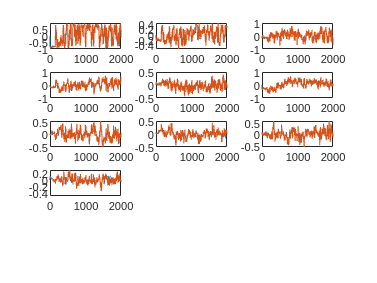

clc;
close all
T = length(data_small);
[n m] = size(A);
x = zeros(n,T);
y = zeros(l,T);



for i = 1:T
    x(:,i+1) = A*x(:,i) + K *( data_small(:,i) - C*x(:,i) );
    y(:,i) = C*x(:,i);
end


figure()
for i=1:l
    subplot(5,3,i)
    plot(y(i,:));hold on;
    plot(data_small(i,:))
end

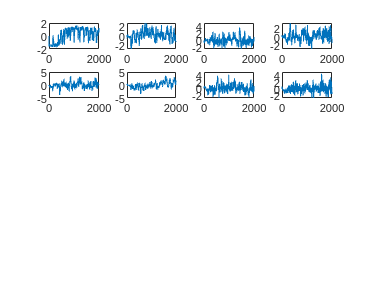



figure()
for i=1:n
    subplot(5,4,i)
    plot(x(i,:));hold on;
end

% x0 = x(:,end);

## Forecast forward

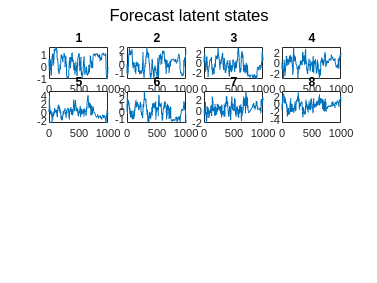

close all;
T = 5000;
data_f = data(1:l,2000:end);

T = length(data_f);
[n m] = size(A);
x = zeros(n,T);
y = zeros(l,T);

xs = zeros(n,T);
ys = zeros(l,T);
% data_f = data(1:l,5000:10000);

%x(:,1) = x0;

for i = 1:T
    x(:,i+1) = A*x(:,i) + K *( data_f(:,i) - C*x(:,i) );
    y(:,i) = C*x(:,i);
    
    xs(:,i+1) = As*xs(:,i) + Ks *( data_f(:,i) - Cs*xs(:,i) );
    ys(:,i) = Cs*xs(:,i);
end



dd = eig(A);


figure()
for i=1:n
    subplot(5,4,i)
    plot(x(i,1:1000));hold on;
    title(num2str(i))
end
sgtitle('Forecast latent states')

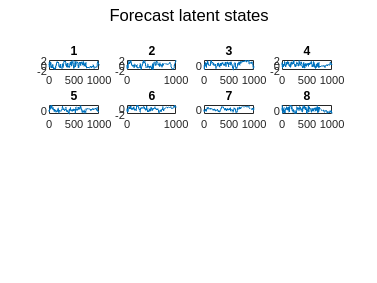


figure()
for i=1:n
    subplot(5,4,i)
    plot(xs(i,1:1000));hold on;
    title(num2str(i))
end
sgtitle('Forecast latent states')

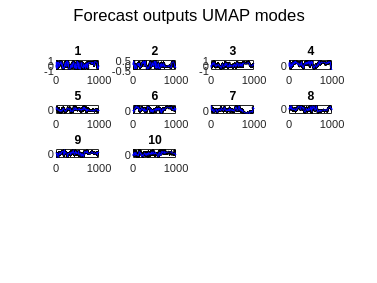


figure()
for i=1:l
    subplot(5,4,i)
    plot(data_f(i,1:1000),'k','Linewidth',2);hold on;
    plot(ys(i,1:1000),'b');
    title(num2str(i))
end
sgtitle('Forecast outputs UMAP modes')

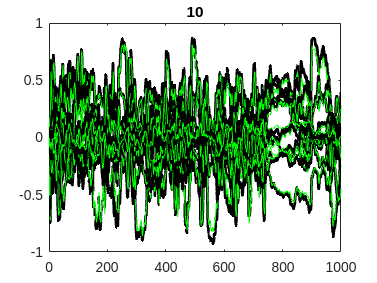


figure()
for i=1:l
    plot(data_f(i,1:1000),'k','Linewidth',2);hold on;
    plot(ys(i,1:1000),'g');
    title(num2str(i))
end

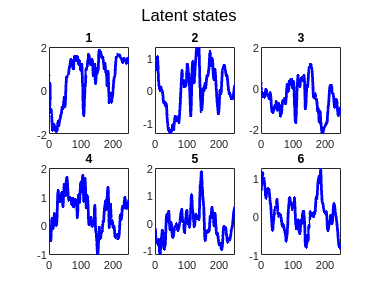

close all;
figure()
for i=1:6
    subplot(2,3,i)
    plot(xs(i,1500:1750),'b','Linewidth',2);hold on;
    title(num2str(i))
end
sgtitle('Latent states')

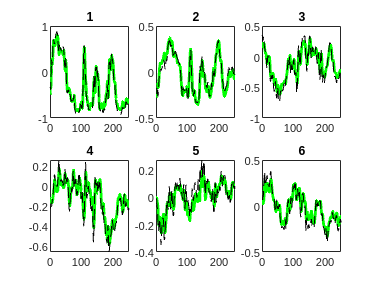

Error using subplot
Index exceeds number of subplots.


figure()
for i=1:l
    subplot(2,3,i)
    plot(ys(i,1500:1750),'g','Linewidth',2);hold on;
    plot(data_f(i,1500:1750),'--k');hold on;
    title(num2str(i))
end

sgtitle('Output modes')

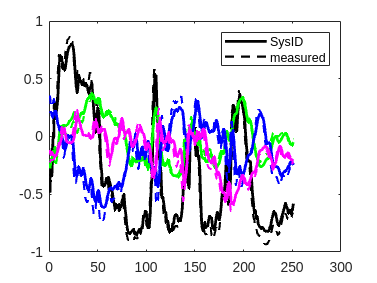

close all
figure()
plot(ys(1,1500:1750),'k','Linewidth',2);hold on;
plot(data_f(1,1500:1750),'--k','Linewidth',1.5);hold on;

plot(ys(2,1500:1750),'g','Linewidth',2);hold on;
plot(data_f(2,1500:1750),'--g','Linewidth',1.5);hold on;

plot(ys(3,1500:1750),'b','Linewidth',2);hold on;
plot(data_f(3,1500:1750),'--b','Linewidth',1.5);hold on;

plot(ys(4,1500:1750),'m','Linewidth',2);hold on;
plot(data_f(4,1500:1750),'--m','Linewidth',1.5);hold on;
% 
% plot(ys(5,1500:1750),'r','Linewidth',2);hold on;
% plot(data_f(5,1500:1750),'--r','Linewidth',1.5);hold on;
legend('SysID','measured')

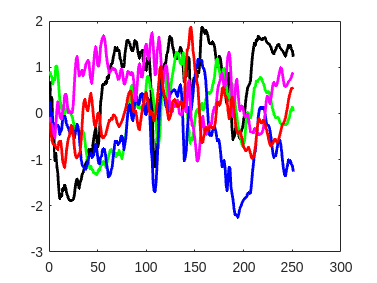

close all
figure()
plot(xs(1,1500:1750),'k','Linewidth',2);hold on;

plot(xs(2,1500:1750),'g','Linewidth',2);hold on;

plot(xs(3,1500:1750),'b','Linewidth',2);hold on;

plot(xs(4,1500:1750),'m','Linewidth',2);hold on;

plot(xs(5,1500:1750),'r','Linewidth',2);hold on;

% writematrix(y,'WF_PCA_forecast_10k.csv','Delimiter',',')
% writematrix(x,'WF_PCA_latent_10k.csv','Delimiter',',')

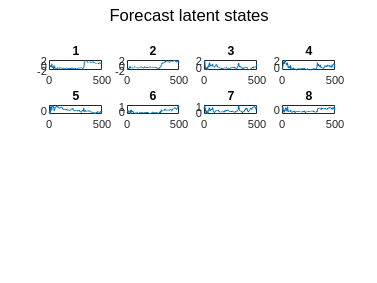

figure()
for i=1:n
    subplot(5,4,i)
    plot(xs(i,4500:5000));hold on;
    title(num2str(i))
end
sgtitle('Forecast latent states')

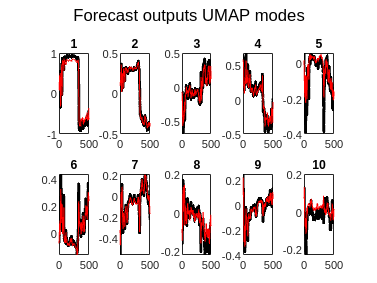



figure()
for i=1:l
    subplot(2,5,i)
    plot(data_f(i,4500:5000),'k','Linewidth',2);hold on;
    plot(ys(i,4500:5000),'r');
    title(num2str(i))
end
sgtitle('Forecast outputs UMAP modes')

dd = eig(A)

dd =    0.9640 + 0.0492i
   0.9640 - 0.0492i
   0.9206 + 0.0073i
   0.9206 - 0.0073i
   0.9387 + 0.0182i
   0.9387 - 0.0182i
   0.9897 + 0.0000i
   0.9751 + 0.0000i


ds = eig(As)

ds =    0.8727 + 0.0946i
   0.8727 - 0.0946i
   0.8999 + 0.0464i
   0.8999 - 0.0464i
   0.8815 + 0.0000i
   0.9047 + 0.0048i
   0.9047 - 0.0048i
   0.9090 + 0.0000i


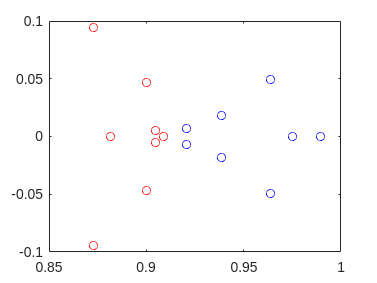

figure()
plot(dd,'ob');hold on
plot(ds,'or');

figure()
for i=1:n
    subplot(5,4,i)
    plot(xs(i,4500:5000));hold on;
    plot(xpf(i,4500:5000))
    title(num2str(i))
end
sgtitle('Forecast latent states')